# EECE 3204: Project

**Name:** Mackenzie Brown

For help with Matlab Publisher formatting issues visit the following page:

[https://www.mathworks.com/help/matlab/matlab_prog/marking-up-matlab-comments-for-publishing.html](https://www.mathworks.com/help/matlab/matlab_prog/marking-up-matlab-comments-for-publishing.html)

**Deliverables:** 

- Matlab Code

- One page report of your project with the following sections: Background Information, Purpose, Methods, Results, and Conclusion.

- A minimum of 5-minutes of presentation of your project.

**Create:** 

A matlab program that takes sound as an input and helps the user tune it to a note

**Simulation:**

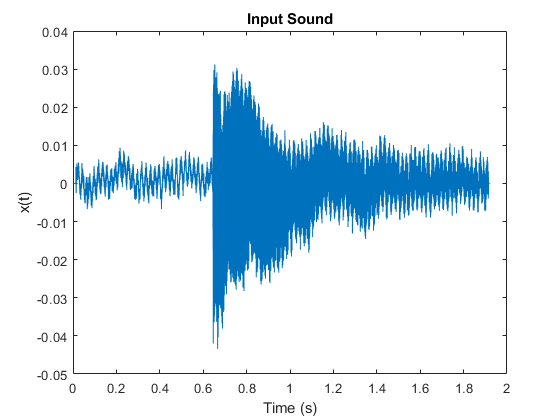

% Extract sound file and display as continuous graph
[x,Fs] = audioread('example1.mp3');
x = x(:,1);
t = linspace(0,length(x)/Fs,length(x));

figure(1)
plot(t,x)
title('Input Sound');
xlabel('Time (s)');
ylabel('x(t)');


% Discretize signal
N = 100;
tmax = 1.41;
tmin = 1.4;

delta_t = (tmax-tmin)/N;
delta_t_calc = (Fs*tmax-Fs*tmin)/N;
n = linspace(0,N,N+1);
td = tmin + n*delta_t;
xd = x(Fs*tmin:delta_t_calc:Fs*tmax);

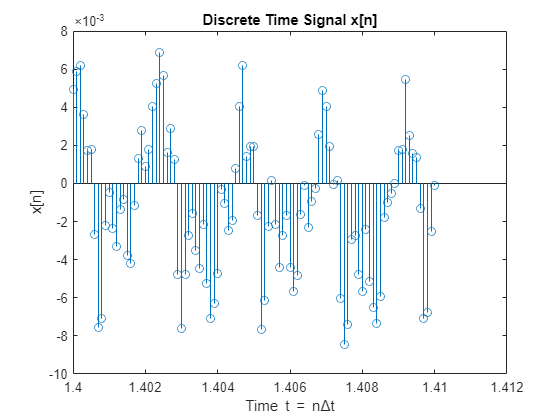


figure(2)
stem(td,xd)
title('Discrete Time Signal x[n]');
xlabel('Time t = n\Deltat');
ylabel('x[n]');

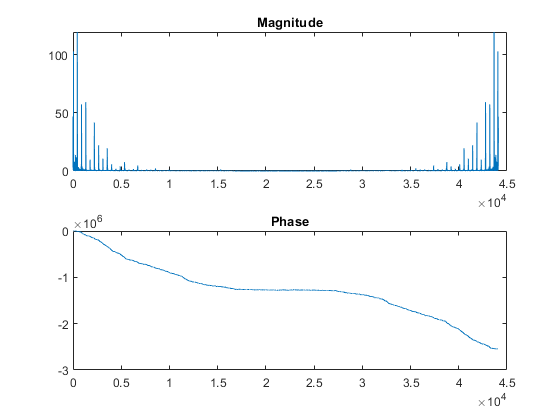


% DTFS of sound
y = fft(x);
m = abs(y);
y(m<1e-6) = 0;
p = unwrap(angle(y));

f = linspace(0,Fs,length(y));

figure(3)
subplot(2,1,1)
plot(f,m)
title('Magnitude')

subplot(2,1,2)
plot(f,p*180/pi)
title('Phase')


% Find Closest Note
maxFreqArray = find(m==max(m));
maxFreq = f(maxFreqArray(1));

notes = ["A","A#","B","C","C#","D","D#","E","F","F#","G","G#"];
noteCalc = round(log2(maxFreq/440)*12);
note = append(notes(mod(noteCalc,12)+1),num2str(4+floor((noteCalc+9)/12)))

note = "A4"

pitch = 440*2^(noteCalc/12)

pitch = 440

pitchDiff = pitch - maxFreq

pitchDiff = -1.9422

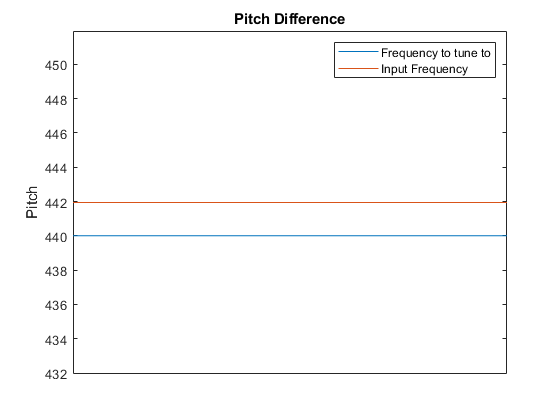


plotPitch = zeros(1,length(x)) + pitch;
plotMaxFreq = zeros(1,length(x)) + maxFreq;
noteDiffT = linspace(0,length(x),length(x));

figure(4)
plot(noteDiffT,plotPitch)
title('Pitch Difference');
ylabel('Pitch');
set(gca,'XTick',[])
axis([0 length(x) max([pitch maxFreq])-10 max([pitch maxFreq])+10])

hold on
plot(noteDiffT,plotMaxFreq)
hold off
legend('Frequency to tune to','Input Frequency')

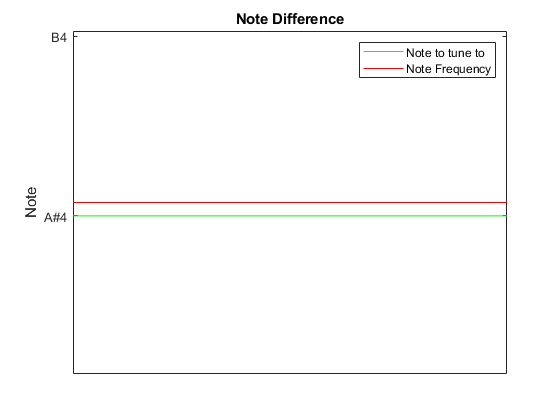



figure(5)
plot(noteDiffT,plotPitch,'-g')
title('Note Difference');
ylabel('Note');
set(gca,'XTick',[])
noteFrequencies = zeros(1,length(notes));
noteNames = notes;
for num = 1:length(notes)
    noteFrequencies(num) = 440*2^((num-1)/12);
    noteNames(num) = append(notes(mod(num,12)+1),num2str(4+floor((num+9)/12)));
end
yticks(noteFrequencies)
yticklabels(noteNames)
axis([0 length(x) max([pitch maxFreq])-25 max([pitch maxFreq])+25])

hold on
plot(noteDiffT,plotMaxFreq,'-r')
hold off
legend('Note to tune to','Note Frequency')